clear

syms f(x) g h
f(x) = x^2

$$f(x) = x^{2}$$

g = sym(0)

$$g = 0$$

h = sym(0)

$$h = 0$$


nElem = 3

nElem = 3

elemDegree = 2

elemDegree = 2

elemContinuity = [-1 1 1 -1]

elemContinuity =     -1     1     1    -1




x = sym("x","real");
xMin = 0;
xMax = 1;

[eCONN,nodes] = generateMesh(xMin,xMax,nElem,elemDegree);

% Create the B-Spline
splineSpace.degree = elemDegree;
splineSpace.uniqueKnotsVector = linspace(xMin,xMax,nElem+1);
splineSpace.continuityVector = elemContinuity;
BSpline = bspline(splineSpace);
% Global Bezier Extraction Operator
M = BSpline.decomposition.globalExtractionOperator;
% Local Bezier Extraction Operators -- access as C{e}
C = BSpline.decomposition.localExtractionOperator;

% Create the local basis functions
bFun = basisFunction("Bernstein", elemDegree, sym("xi","real"), [-1 1]);
ELEM = createElements(BSpline,bFun);



figure
hold on

LN1 = C{1}*ELEM(1).LBasisFuns

$$LN1(xi) = \left[\begin{array}{c} \frac{{\left(\xi -1\right)}^{2}}{4}\\ \frac{{\left(\xi +1\right)}^{2}}{8}-\left(\frac{\xi }{2}-\frac{1}{2}\right)\,\left(\xi +1\right)\\ \frac{{\left(\xi +1\right)}^{2}}{8} \end{array}\right]$$

LN1 = symfun(LN1,symvar(LN1));
GN1 = LN1(ELEM(1).GlobalVariate_to_LocalVariate)

$$GN1 = \left[\begin{array}{c} \frac{{\left(6\,x-2\right)}^{2}}{4}\\ \frac{9\,x^{2}}{2}-6\,x\,\left(3\,x-1\right)\\ \frac{9\,x^{2}}{2} \end{array}\right]$$

fplot(GN1,ELEM(1).GDomain,'b')

LN2 = C{2}*ELEM(2).LBasisFuns

$$LN2(xi) = \left[\begin{array}{c} \frac{{\left(\xi -1\right)}^{2}}{8}\\ \frac{{\left(\xi -1\right)}^{2}}{8}+\frac{{\left(\xi +1\right)}^{2}}{8}-\left(\frac{\xi }{2}-\frac{1}{2}\right)\,\left(\xi +1\right)\\ \frac{{\left(\xi +1\right)}^{2}}{8} \end{array}\right]$$

LN2 = symfun(LN2,symvar(LN2));
GN2 = LN2(ELEM(2).GlobalVariate_to_LocalVariate)

$$GN2 = \left[\begin{array}{c} \frac{{\left(6\,x-4\right)}^{2}}{8}\\ \frac{{\left(6\,x-2\right)}^{2}}{8}+\frac{{\left(6\,x-4\right)}^{2}}{8}-\left(3\,x-2\right)\,\left(6\,x-2\right)\\ \frac{{\left(6\,x-2\right)}^{2}}{8} \end{array}\right]$$

fplot(GN2,ELEM(2).GDomain,'r')

LN3 = C{3}*ELEM(3).LBasisFuns

$$LN3(xi) = \left[\begin{array}{c} \frac{{\left(\xi -1\right)}^{2}}{8}\\ \frac{{\left(\xi -1\right)}^{2}}{8}-\left(\frac{\xi }{2}-\frac{1}{2}\right)\,\left(\xi +1\right)\\ \frac{{\left(\xi +1\right)}^{2}}{4} \end{array}\right]$$

LN3 = symfun(LN3,symvar(LN3));
GN3 = LN3(ELEM(3).GlobalVariate_to_LocalVariate)

$$GN3 = \left[\begin{array}{c} \frac{{\left(6\,x-6\right)}^{2}}{8}\\ \frac{{\left(6\,x-6\right)}^{2}}{8}-\left(3\,x-3\right)\,\left(6\,x-4\right)\\ \frac{{\left(6\,x-4\right)}^{2}}{4} \end{array}\right]$$

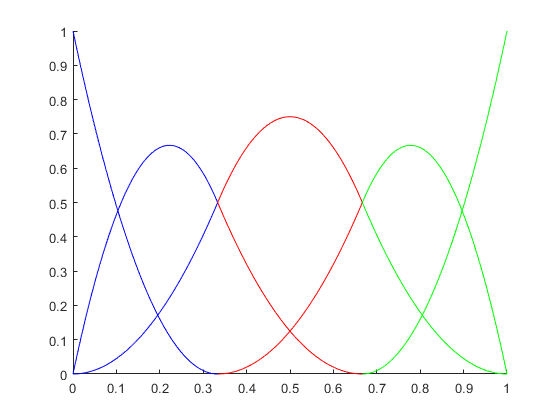

fplot(GN3,ELEM(3).GDomain,'g')


% LN4 = C{4}*ELEM(4).LBasisFuns
% LN4 = symfun(LN4,symvar(LN4));
% GN4 = LN4(ELEM(4).GlobalVariate_to_LocalVariate)
% fplot(GN4,ELEM(4).GDomain,'m')


dGN1 = diff(GN1)

$$dGN1 = \left[\begin{array}{c} 18\,x-6\\ 6-27\,x\\ 9\,x \end{array}\right]$$

dGN2 = diff(GN2)

$$dGN2 = \left[\begin{array}{c} 9\,x-6\\ 9-18\,x\\ 9\,x-3 \end{array}\right]$$

dGN3 = diff(GN3)

$$dGN3 = \left[\begin{array}{c} 9\,x-9\\ 21-27\,x\\ 18\,x-12 \end{array}\right]$$

% dGN4 = diff(GN4)

k1 = [int(dGN1(1)*dGN1(1),[0 1/4]), int(dGN1(1)*dGN1(2),[0 1/4]), int(dGN1(1)*dGN1(3),[0 1/4]);...
    int(dGN1(2)*dGN1(1),[0 1/4]), int(dGN1(2)*dGN1(2),[0 1/4]), int(dGN1(2)*dGN1(3),[0 1/4]);...
    int(dGN1(3)*dGN1(1),[0 1/4]), int(dGN1(3)*dGN1(2),[0 1/4]), int(dGN1(3)*dGN1(3),[0 1/4])]

$$k1 = \left[\begin{array}{ccc} \frac{63}{16} & -\frac{99}{32} & -\frac{27}{32}\\ -\frac{99}{32} & \frac{171}{64} & \frac{27}{64}\\ -\frac{27}{32} & \frac{27}{64} & \frac{27}{64} \end{array}\right]$$


k2 = [int(dGN2(1)*dGN2(1),[1/4 1/2]), int(dGN2(1)*dGN2(2),[1/4 1/2]), int(dGN2(1)*dGN2(3),[1/4 1/2]);...
    int(dGN2(2)*dGN2(1),[1/4 1/2]), int(dGN2(2)*dGN2(2),[1/4 1/2]), int(dGN2(2)*dGN2(3),[1/4 1/2]);...
    int(dGN2(3)*dGN2(1),[1/4 1/2]), int(dGN2(3)*dGN2(2),[1/4 1/2]), int(dGN2(3)*dGN2(3),[1/4 1/2])]

$$k2 = \left[\begin{array}{ccc} \frac{117}{64} & -\frac{27}{16} & -\frac{9}{64}\\ -\frac{27}{16} & \frac{27}{16} & 0\\ -\frac{9}{64} & 0 & \frac{9}{64} \end{array}\right]$$


k3 = [int(dGN3(1)*dGN3(1),[1/2 3/4]), int(dGN3(1)*dGN3(2),[1/2 3/4]), int(dGN3(1)*dGN3(3),[1/2 3/4]);...
    int(dGN3(2)*dGN3(1),[1/2 3/4]), int(dGN3(2)*dGN3(2),[1/2 3/4]), int(dGN3(2)*dGN3(3),[1/2 3/4]);...
    int(dGN3(3)*dGN3(1),[1/2 3/4]), int(dGN3(3)*dGN3(2),[1/2 3/4]), int(dGN3(3)*dGN3(3),[1/2 3/4])]

$$k3 = \left[\begin{array}{ccc} \frac{189}{64} & -\frac{243}{64} & \frac{27}{32}\\ -\frac{243}{64} & \frac{333}{64} & -\frac{45}{32}\\ \frac{27}{32} & -\frac{45}{32} & \frac{9}{16} \end{array}\right]$$


% k4 = [int(dGN4(1)*dGN4(1),[3/4 1]), int(dGN4(1)*dGN4(2),[3/4 1]), int(dGN4(1)*dGN4(3),[3/4 1]);...
%     int(dGN4(2)*dGN4(1),[3/4 1]), int(dGN4(2)*dGN4(2),[3/4 1]), int(dGN4(2)*dGN4(3),[3/4 1]);...
%     int(dGN4(3)*dGN4(1),[3/4 1]), int(dGN4(3)*dGN4(2),[3/4 1]), int(dGN4(3)*dGN4(3),[3/4 1])]


K = sym(zeros(length(BSpline.nodes)));
gID = BSpline.elementConnectivity(:,1)

gID =      1
     2
     3


K(gID,gID) = K(gID,gID) + k1

$$K = \left[\begin{array}{ccccc} \frac{63}{16} & -\frac{99}{32} & -\frac{27}{32} & 0 & 0\\ -\frac{99}{32} & \frac{171}{64} & \frac{27}{64} & 0 & 0\\ -\frac{27}{32} & \frac{27}{64} & \frac{27}{64} & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right]$$


gID = BSpline.elementConnectivity(:,2)

gID =      2
     3
     4


K(gID,gID) = K(gID,gID) + k2

$$K = \left[\begin{array}{ccccc} \frac{63}{16} & -\frac{99}{32} & -\frac{27}{32} & 0 & 0\\ -\frac{99}{32} & \frac{9}{2} & -\frac{81}{64} & -\frac{9}{64} & 0\\ -\frac{27}{32} & -\frac{81}{64} & \frac{135}{64} & 0 & 0\\ 0 & -\frac{9}{64} & 0 & \frac{9}{64} & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right]$$


gID = BSpline.elementConnectivity(:,3)

gID =      3
     4
     5


K(gID,gID) = K(gID,gID) + k3

$$K = \left[\begin{array}{ccccc} \frac{63}{16} & -\frac{99}{32} & -\frac{27}{32} & 0 & 0\\ -\frac{99}{32} & \frac{9}{2} & -\frac{81}{64} & -\frac{9}{64} & 0\\ -\frac{27}{32} & -\frac{81}{64} & \frac{81}{16} & -\frac{243}{64} & \frac{27}{32}\\ 0 & -\frac{9}{64} & -\frac{243}{64} & \frac{171}{32} & -\frac{45}{32}\\ 0 & 0 & \frac{27}{32} & -\frac{45}{32} & \frac{9}{16} \end{array}\right]$$


% gID = BSpline.elementConnectivity(:,4)
% K(gID,gID) = K(gID,gID) + k4

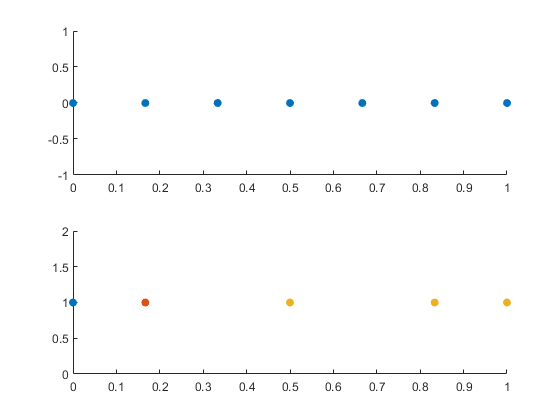

sNodes = 1×1 cell array
    {3×1 sym}


sNodes = 1×2 cell array
    {3×1 sym}    {3×1 sym}


sNodes = 1×3 cell array
    {3×1 sym}    {3×1 sym}    {3×1 sym}



figure
% Plot Bezier nodes
subplot(2,1,1)
scatter(nodes,zeros(size(nodes)),'o','filled')
% Plot Spline nodes
subplot(2,1,2)
hold on
for e = 1:3
    sNodes{e} = inv(C{e}') * nodes(eCONN(:,e))'
    scatter(sNodes{e},ones(size(sNodes{e})),'o','filled')
end


size(M)

ans =      5     7


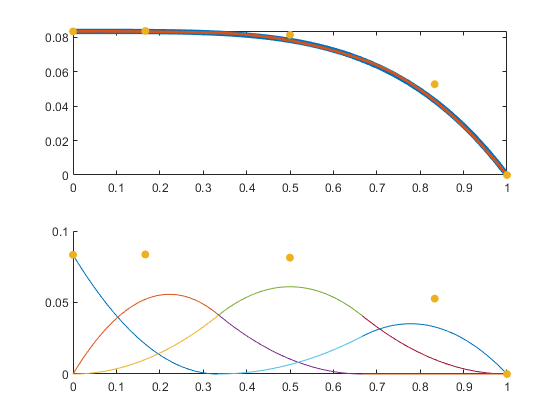

clear

syms f(x) g h
f(x) = x^2;
% f(x) = -sin(x*2*pi)-cos(x*pi);
g = sym(0);
h = sym(0);

E = computeExactSolution(f,g,h);
FE = main(3, 2, [-1 1 1 -1], f, g, h);
% FE = main(4, 4, [-1 3 3 3 -1], f, g, h);

figure
subplot(2,1,1)
fplot(E.U,[0 1],'LineWidth',4)
hold on
fplot(FE.U,[0 1],'LineWidth',2)
scatter(FE.Spline.nodes,FE.LinearSystem.d,'o','filled')

subplot(2,1,2)
hold on
C = FE.Spline.decomposition.localExtractionOperator;
for e = 1:FE.Spline.numcells
    N = C{e}*FE.Spline.decomposition.spline.basis.functions(FE.Spline.decomposition.localExtractionSupportedBezierBases{e});
    locBasisFuns = FE.Spline.decomposition.localExtractionSupportedSplineBases{e};
    for ii = 1:length(locBasisFuns)
        fplot(N(ii)*FE.LinearSystem.d(locBasisFuns(ii)),FE.Elements(e).GDomain)
    end
end
scatter(FE.Spline.nodes,FE.LinearSystem.d,'o','filled')